## Final Project

Enrique Almazán Sánchez

syms ROS syn ERS mTOR B1 C

## Parameters

% THREE STRESSES
S1 = 2;      % Internal or external oxidative stress -> Promote ROS
S2 = 1;      % Age-related anti-oxidative mechanisms -> Degrades ROS
S3 = 1;      % Influence of genetic damage -> Promotes the formation of αSyn

dAlphaSyn = 15; % αSyn∗-dependent fractional activation of ROS

% Rate Constants
kAlphaSyn = 8.5;     % Hill constant of αSyn∗ aggregation
k1 = 0.72;           % Generation rate of ROS
k2 = 0.72;           % Removal rate constant of ROS
k3 = 0.7;            % Generation rate constant of αSyn∗
k4 = 0.7;            % Removal rate constant of αSyn∗
k5 = 2.7;            % Beclin1- and mTOR-dependent rate constant of αSyn∗ degradation
k6 = 1;              % αSyn∗-dependent rate constant of ERS activation
k7 = 0.5;            % Basal rate constant of ERS activation
k8 = 1;              % Basal rate constant of ERS inactivation
k9 = 2;              % Basal rate of mTOR activation
k10 = 10;            % ERS-dependent rate constant of mTOR activation
k11 = 0.4;           % Basal rate of mTOR inactivation
k12 = 7;             % Beclin1-dependent rate constant of mTOR inactivation
k13 = 2;             % Basal rate of Beclin1 activation
k14 = 4;             % ERS-dependent rate constant of Beclin1 activation
k15 = 1;             % Basal rate of Beclin1 inactivation
k16 = 10;            % Caspases-dependent rate constant of Beclin1 inactivation
k17 = 0.6;           % mTOR-dependent rate constant of Beclin1 inactivation
k18 = 1;             % Basal rate of Caspases inactivation
k19 = 2;             % ERS-dependent rate constant of Caspases activation
k20 = 2;             % mTOR-dependent rate constant of Caspases activation
k21 = 2;             % Basal rate of Caspases inactivation
k22 = 4.5;           % Beclin1-dependent rate constant of Caspases inactivation

% Michaelis Constants
Jbe = 1;    % Beclin1 Michaelis constant
Jca = 0.04; % Caspases Michaelis constant

% Total Levels
ERST = 2;           % Total level of ERS
mTORT = 1;          % Total level of mTOR
Beclin1T = 1;       % Total level of Beclin1
CaspasesT = 1;      % Total level of Caspases

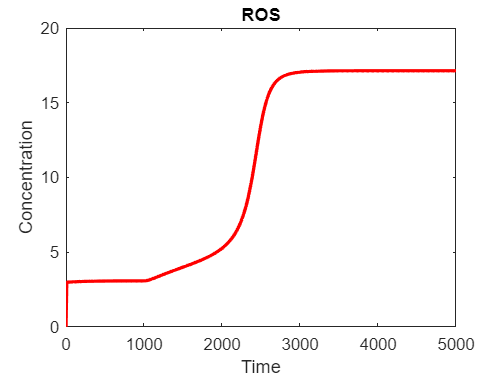

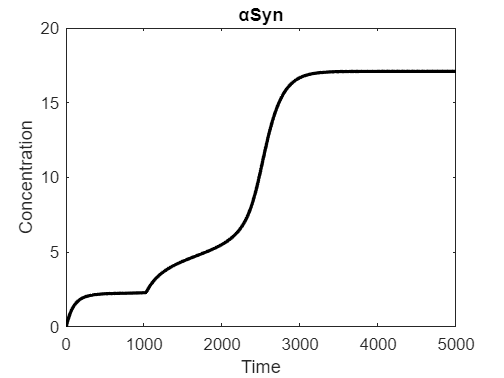

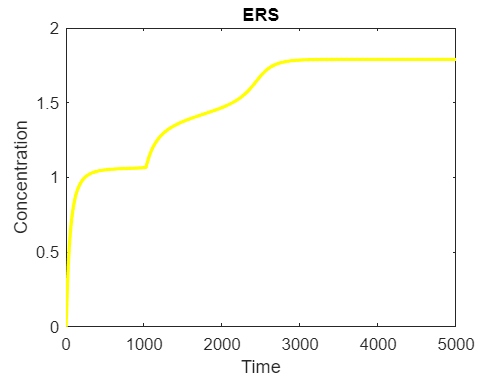

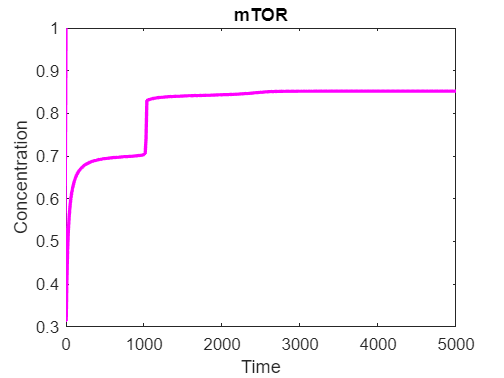

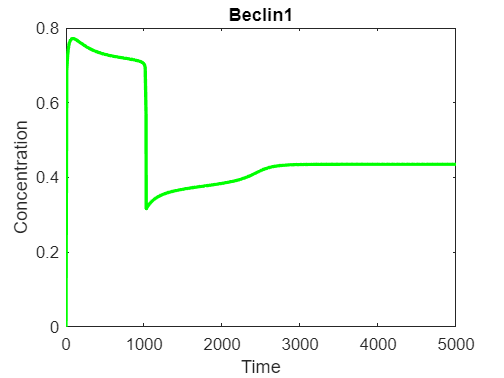

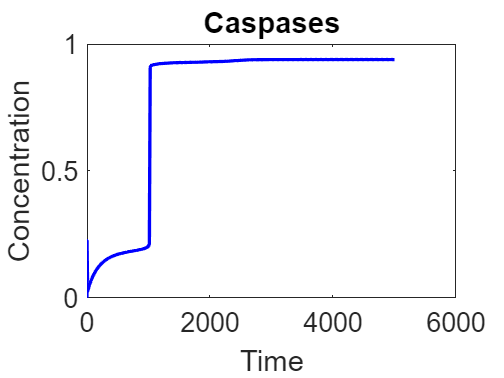

time()


% Set initial conditions
initialConditions = [0; 0; 0; 1; 0; 0];

% Time span
tspan = [0 3000];

% Solve ODEs
options = odeset('RelTol', 1e-6, 'AbsTol', 1e-8);
[t, y] = ode45(@(t, y) odefun(y, S1, S2, S3, k1, k2, k3, k4, k5, syn, syn, k6, k7, k8, ERST, k9, k10, k11, k12, mTORT, Jbe, k13, k14, k15, k16, k17, Beclin1T, Jca, k18, k19, k20, k21, k22, CaspasesT), tspan, initialConditions, options);

Error using odefun
Too many input arguments.

Error in untitled (line 53)
[t, y] = ode45(@(t, y) odefun(y, S1, S2, S3, k1, k2, k3, k4, k5, syn, syn, k6, k7, k8, ERST, k9, k10, k11, k12, mTORT, Jbe, k13, k14, k15, k16, k17, Beclin1T, Jca, k18, k19, k20, k21, k22, CaspasesT), tspan, initialConditions, options);

Error in 


% Plot results
figure;
plot(t, y(:, 1));
xlabel('Time');
ylabel('Ros');
title('ROS Concentration');

figure;
plot(t, y(:, 2));
xlabel('Time');
ylabel('Syn');
title('Alpha-Synuclein Concentration');

figure;
plot(t, y(:, 3));
xlabel('Time');
ylabel('ERS');
title('Endoplasmic Reticulum Stress');

figure;
plot(t, y(:, 4));
xlabel('Time');
ylabel('mTOR');
title('mTOR Concentration');

figure;
plot(t, y(:, 5));
xlabel('Time');
ylabel('Beca');
title('Beclin1 Concentration');

figure;
plot(t, y(:, 6));
xlabel('Time');
ylabel('Casp');
title('Caspases Concentration');
